clear

## **Lista de funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

disp("--------------- Variveis globais --------------");

--------------- Variveis globais --------------


Nvar = 2;
Nmax = randi([35,50])

Nmax = 40

errodf = 15e-2

errodf = 0.1500

NPontosIniciais = randi([8,13])

NPontosIniciais = 10

x_values=[-11;-11]; y_values=[7;7];

disp("------------------- Outputs -------------------");

------------------- Outputs -------------------



PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
%Inicio timer
tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste1 = toc

tempo_execucao_teste1 = 3.1281

xopt_teste1 = minGlobal(Lopt, g)

xopt_teste1 =    -1.8706
   -1.8706


taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste1 = 5.6000

tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste1 = 'Convergência para um mínimo global'

[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g)

minimos_locais_teste1 =    -1.8709   -1.8706
   -1.8707   -1.8716


minimizantes_locais_teste1 =  -141.3956 -141.3955


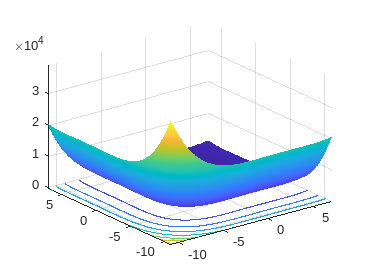

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

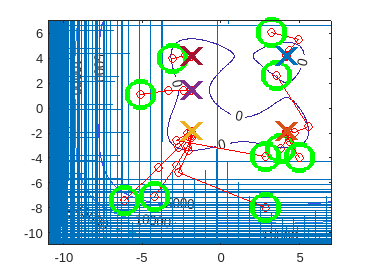


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(r, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2 = toc

tempo_execucao_teste2 = 15.3162

xopt_teste2 = minGlobal(Lopt, r)

xopt_teste2 =     1.0012
    1.0023


taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste2 = 26.5000

tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste2 = 'Convergência para um mínimo global'

[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste2 =     1.0109    1.0032    1.0021
    1.0219    1.0063    1.0042


minimizantes_locais_teste2 = 1.0e+03 *

    6.3079    6.3115    6.3120


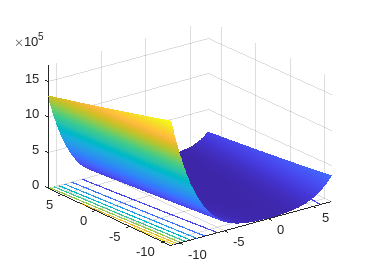

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

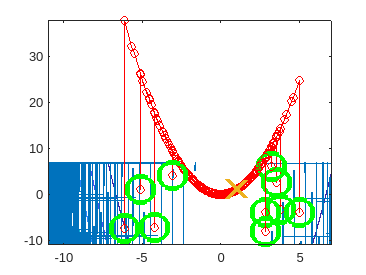


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(f, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3 = toc

tempo_execucao_teste3 = 8.2387

xopt_teste3 = minGlobal(Lopt, f)

xopt_teste3 =    -8.9548
   -4.5477


taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste3 = 12.9000

tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste3 = 'Convergência para um mínimo global'

[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste3 =    -8.9548    8.9928
   -4.5477   -4.5183


minimizantes_locais_teste3 =  -408.7072 -396.7978


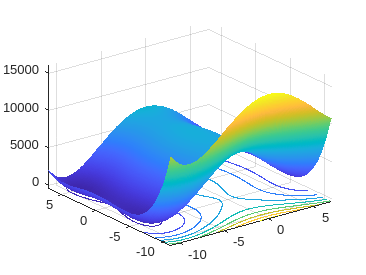

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

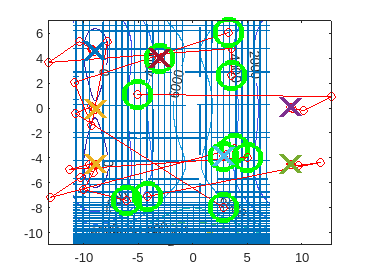


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

T = table([tempo_execucao_teste1; tempo_execucao_teste2; tempo_execucao_teste3], ...
          [taxa_media_convergencia_teste1; taxa_media_convergencia_teste2; taxa_media_convergencia_teste3], ...
          {tipo_convergencia_teste1; tipo_convergencia_teste2; tipo_convergencia_teste3}, ...
          'VariableNames', {'Tempo de Execucao', 'Taxa Media de Convergencia', 'Tipo de Convergencia'}, ...
          'RowNames', {'Teste1', 'Teste2', 'Teste3'});

disp(T);

              Tempo de Execucao    Taxa Media de Convergencia             Tipo de Convergencia         
              _________________    __________________________    ______________________________________

    Teste1         3.1281                      5.6               {'Convergência para um mínimo global'}
    Teste2         15.316                     26.5               {'Convergência para um mínimo global'}
    Teste3         8.2387                     12.9               {'Convergência para um mínimo global'}

